# Rappresentazione Asse-Angolo

La rappresentazione Asse-Angolo è un metodo per descrivere l'orientamento di un corpo rigido nello spazio. Utilizza quattro parametri:

- Un **versore** $\mathbf{r}=[r_X ,r_Y ,r_Z ]$ che definisce l'asse attorno al quale avviene la rotazione.

- Un **angolo** $\theta$, che indica l'ampiezza della rotazione attorno a tale asse.

## Problema Diretto

Il problema diretto consiste nel determinare la matrice di rotazione $R\bigl(\theta ,\mathbf{r}\bigr)$ partendo da un asse $\mathbf{r}$ e un angolo $\theta$. La matrice di rotazione si ottiene tramite la *formula di Rodrigues*, derivata dalla composizione di rotazioni elementari:


$$R(\theta ,r)=rr^T +(I-rr^T )\cos (\theta )+S(r)\sin (\theta )$$


Dove:

$I$ è la matrice identità 3x3.

$rr^T$ è il prodotto esterno del versore $\mathbf{r}$.

$S(r)$ è la Skew-Symmetric Matrix associata a $\mathbf{r}$, che rappresenta l'operatore prodotto vettoriale:


$$S(r)=\left(\begin{array}{ccc} 0 & -r_z & r_y \\ r_z & 0 & -r_x \\ -r_y & r_x & 0 \end{array}\right)$$


% Risoluzione percorso cartella funzioni ausiliarie Codici Matlab
if ~exist('Compute_DH_Transformations', 'file') || ~exist('Compute_Rotation_Matrix', 'file')
    candDirs = {pwd, fileparts(pwd)};
    try
        edFile = matlab.desktop.editor.getActiveFilename;
        candDirs = [candDirs, {fileparts(edFile), fileparts(fileparts(edFile))}];
    catch
    end
    for iCand = 1:numel(candDirs)
        cDir = candDirs{iCand};
        if isfolder(cDir) && (isfile(fullfile(cDir, 'Compute_DH_Transformations.m')) || isfile(fullfile(cDir, 'Compute_Rotation_Matrix.m')))
            addpath(cDir);
            break;
        end
    end
end
clc; clear; close all;
% Definizione variabili simboliche
syms rx ry rz theta real

% Definiamo il versore r come un vettore colonna
r = [rx; ry; rz];
[R] = Compute_Rotation_Matrix(r, theta);

disp("Matrice Di Rotazione R(theta, r):");

Matrice Di Rotazione R(theta, r):


disp(R);

$$\begin{array}{l} \left(\begin{array}{ccc} {\mathrm{rx}}^{2}-\cos\left(\theta \right)\,\left({\mathrm{rx}}^{2}-1\right) & \mathrm{rx}\,\mathrm{ry}-\mathrm{rz}\,\sin\left(\theta \right)-\sigma_{3} & \mathrm{rx}\,\mathrm{rz}+\mathrm{ry}\,\sin\left(\theta \right)-\sigma_{2}\\ \mathrm{rx}\,\mathrm{ry}+\mathrm{rz}\,\sin\left(\theta \right)-\sigma_{3} & {\mathrm{ry}}^{2}-\cos\left(\theta \right)\,\left({\mathrm{ry}}^{2}-1\right) & \mathrm{ry}\,\mathrm{rz}-\mathrm{rx}\,\sin\left(\theta \right)-\sigma_{1}\\ \mathrm{rx}\,\mathrm{rz}-\mathrm{ry}\,\sin\left(\theta \right)-\sigma_{2} & \mathrm{ry}\,\mathrm{rz}+\mathrm{rx}\,\sin\left(\theta \right)-\sigma_{1} & {\mathrm{rz}}^{2}-\cos\left(\theta \right)\,\left({\mathrm{rz}}^{2}-1\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{ry}\,\mathrm{rz}\,\cos\left(\theta \right)\\ \sigma_{2}=\mathrm{rx}\,\mathrm{rz}\,\cos\left(\theta \right)\\ \sigma_{3}=\mathrm{rx}\,\mathrm{ry}\,\cos\left(\theta \right) \end{array}$$

### Calcoli Numerici Problema Diretto

Si calcola la matrice di rotazione numerica e successivamente si verificano le proprietà fondamentali.

% Definizione del vettore r e dell'angolo theta numerici
rNum = [1; 2; 3];
thetaNum = 3*pi/5;

% Verifica se il vettore r ha 3 componenti
if numel(rNum) == 3
    disp("Il Vettore r Ha 3 Componenti!");
else
    % Uso 'error' per interrompere l'esecuzione in caso di errore
    error("Il Vettore r Deve Avere 3 Componenti!");
end

Il Vettore r Ha 3 Componenti!


% Verifica se theta è uno scalare
if isscalar(thetaNum)
    disp("Theta È Uno Scalare");
else
    % Uso 'error' per interrompere l'esecuzione in caso di errore
    error("Theta Deve Essere Uno Scalare!");
end

Theta È Uno Scalare


% Si controlla che r sia un vettore colonna 3x1
rNum = reshape(rNum, [3, 1]);

% Calcolo della norma di r
norm_rNum = norm(rNum);


if norm_rNum > 0
    % Il vettore r ha una direzione ben definita (non è il vettore nullo).
    % Normalizzo il vettore r per ottenere un vettore unitario che
    % rappresenta l'asse di rotazione.

    disp("Normalizzo Il Vettore r...");
    rNum = rNum / norm_rNum;

    disp("Vettore r Normalizzato:");
    disp(rNum);
else
    % Se la norma è nulla, il vettore r è il vettore nullo.
    % Non c'è alcuna direzione valida per l'asse di rotazione.
    % Imposto theta = 0 per indicare che non c'è rotazione (R = I).
    disp("Il Vettore r È Nullo. Imposto Theta = 0.");
    thetaNum = 0;
end

Normalizzo Il Vettore r...


Vettore r Normalizzato:


    0.2673
    0.5345
    0.8018



[R] = Compute_Rotation_Matrix(rNum, thetaNum);

disp("Matrice Di Rotazione R(theta, r) Numerica:");

Matrice Di Rotazione R(theta, r) Numerica:


disp(R);

   -0.2155   -0.5755    0.7889
    0.9495    0.0650    0.3068
   -0.2279    0.8152    0.5325



Una matrice di rotazione **R** gode di importanti proprietà:

- **Ortogonalità:** La matrice è ortogonale, ovvero la sua inversa coincide con la sua trasposta $(R^T R=I)$.

- **Determinante Unitario:** $\det (R)=1$

- **Traccia: **La traccia è legata all'angolo di rotazione dalla formula $\textrm{trace}(R)=1+2\cos (\theta )$.

checkOrt = R' * R;
disp('Verifica Ortogonalità (R'' * R):');

Verifica Ortogonalità (R' * R):


disp(checkOrt);

    1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000



detR = det(R);
fprintf('Determinante Di R: %f\n\n', detR);

Determinante Di R: 1.000000



traceR = trace(R);
traceSim = 1 + 2*cos(thetaNum);
fprintf('Traccia Calcolata Di R: %f\n', traceR);

Traccia Calcolata Di R: 0.381966


fprintf('Valore Atteso (1 + 2*cos(theta)): %f\n', traceSim);

Valore Atteso (1 + 2*cos(theta)): 0.381966


## Problema Inverso

Il problema inverso consiste nel determinare l'asse **r **e l'angolo $\theta$ a partire da una matrice di rotazione **R **nota.

Dalla relazione della traccia, si può isolare l'angolo $\theta$:


$$\textrm{trace}(R)=1+2\cos (\theta )~~\longrightarrow ~~\theta =\arccos \left(\frac{\textrm{trace}(R)-1}{2}\right)$$


Questa formula restituisce un angolo nell'intervallo $[0,\pi ]$.

Per trovare l'asse di rotazione **r**, si sfrutta la parte antisimmetrica della matrice **R:**


$$R-R^T =2\sin (\theta )\;S(\mathbf{r})$$


Da questa relazione, si possono estrarre le componenti di **r**:


$$\mathbf{r}=\frac{1}{2\sin (\theta )}\;\left(\begin{array}{c} r_{32} -r_{23} \\ r_{13} -r_{31} \\ r_{21} -r_{12} \end{array}\right)$$


Questo metodo è valido solo se $\sin (\theta )\not= 0$, ovvero per angoli di rotazione diversi da 0 e $k\pi$

% Calcolo dell'angolo theta dalla traccia
cosTheta = (trace(R) - 1) / 2;
thetaCalc = acos(cosTheta);

% Calcolo dell'asse r
rCalc = [NaN; NaN; NaN];
sinTheta = sin(thetaCalc);

if abs(sinTheta) < 1e-9
    disp('Theta È 0 o pi. Asse Non È Definito Univocamente Con Questa Formula.');
else
    % Si estraggono le componenti dalla parte antisimmetrica di R
    rVec = [R(3,2) - R(2,3); R(1,3) - R(3,1); R(2,1) - R(1,2)];
    rCalc = (1 / (2 * sinTheta)) * rVec;
end

disp('Valori Input:');

Valori Input:


fprintf('Theta = %.4f rad\n', thetaNum);

Theta = 1.8850 rad


disp('Vettore r =');

Vettore r =


disp(rNum);

    0.2673
    0.5345
    0.8018



disp('Valori Calcolati Dal Problema Inverso:');

Valori Calcolati Dal Problema Inverso:


fprintf('Theta Calcolato = %.4f rad\n', thetaCalc);

Theta Calcolato = 1.8850 rad


disp('Vettore r Calcolato =');

Vettore r Calcolato =


disp(rCalc);

    0.2673
    0.5345
    0.8018



% Calcolo dell'errore per verificare la correttezza
fprintf('Errore Su Theta: %e\n', abs(thetaNum - thetaCalc));

Errore Su Theta: 0.000000e+00


fprintf('Errore Su r: %e\n', norm(rNum - rCalc));

Errore Su r: 0.000000e+00


## Visualizzazione Grafica

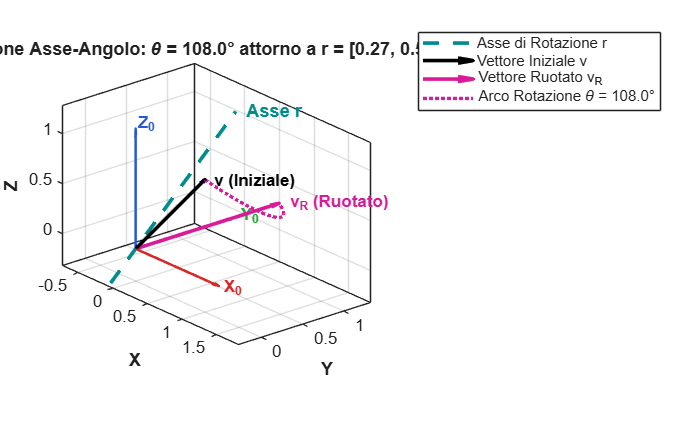

% Assi Sistema Riferimento
AsseX = [1, 0, 0];
AsseY = [0, 1, 0];
AsseZ = [0, 0, 1];

% Vettore Da Ruotare
v = [1; 0; 1];

% Calcolo Vettore Ruotato
vR = R * v;

% Impostazioni Figura
figure('Name', 'Rotazione Asse-Angolo (Formula di Rodrigues)', 'Color', 'w');
hold on;
grid on;
box on;
xlabel('X', 'FontWeight', 'bold');
ylabel('Y', 'FontWeight', 'bold');
zlabel('Z', 'FontWeight', 'bold');
axis equal;
view(50, 22);

% Disegno Assi Cartesiani di Riferimento
col_X = [0.85, 0.15, 0.15];
col_Y = [0.15, 0.65, 0.20];
col_Z = [0.15, 0.35, 0.85];

h_axX = quiver3(0, 0, 0, AsseX(1)*1.2, AsseX(2)*1.2, AsseX(3)*1.2, 0, 'Color', col_X, 'LineWidth', 1.5);
h_axY = quiver3(0, 0, 0, AsseY(1)*1.2, AsseY(2)*1.2, AsseY(3)*1.2, 0, 'Color', col_Y, 'LineWidth', 1.5);
h_axZ = quiver3(0, 0, 0, AsseZ(1)*1.2, AsseZ(2)*1.2, AsseZ(3)*1.2, 0, 'Color', col_Z, 'LineWidth', 1.5);

text(AsseX(1)*1.25, AsseX(2)*1.25, AsseX(3)*1.25, 'X_0', 'Color', col_X, 'FontWeight', 'bold');
text(AsseY(1)*1.25, AsseY(2)*1.25, AsseY(3)*1.25, 'Y_0', 'Color', col_Y, 'FontWeight', 'bold');
text(AsseZ(1)*1.25, AsseZ(2)*1.25, AsseZ(3)*1.25, 'Z_0', 'Color', col_Z, 'FontWeight', 'bold');

% Disegno Asse Rotazione r
r_scale = 1.6;
h_axis = plot3([-rNum(1)*0.4, rNum(1)*r_scale], ...
               [-rNum(2)*0.4, rNum(2)*r_scale], ...
               [-rNum(3)*0.4, rNum(3)*r_scale], ...
               '--', 'Color', [0.0 0.55 0.55], 'LineWidth', 2.2);
text(rNum(1)*r_scale, rNum(2)*r_scale, rNum(3)*r_scale, '  Asse r', ...
    'Color', [0.0 0.55 0.55], 'FontSize', 11, 'FontWeight', 'bold');

% Disegno Vettore Iniziale v e Ruotato vR
h_v  = quiver3(0, 0, 0, v(1), v(2), v(3), 0, 'Color', 'k', 'LineWidth', 2.2);
h_vR = quiver3(0, 0, 0, vR(1), vR(2), vR(3), 0, 'Color', [0.85 0.1 0.6], 'LineWidth', 2.2);
text(v(1), v(2), v(3), '  v (Iniziale)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'k');
text(vR(1), vR(2), vR(3), '  v_R (Ruotato)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.85 0.1 0.6]);

% Arco 3D di Rotazione Spazzato tra 0 e theta
th_samples = linspace(0, thetaNum, 60);
arc_pts = zeros(3, length(th_samples));
for k = 1:length(th_samples)
    R_k = Compute_Rotation_Matrix(rNum, th_samples(k));
    arc_pts(:, k) = R_k * v;
end
h_arc = plot3(arc_pts(1,:), arc_pts(2,:), arc_pts(3,:), ':', ...
    'Color', [0.85 0.1 0.6], 'LineWidth', 2.0);

% Legenda e Titolo
legend([h_axis, h_v, h_vR, h_arc], ...
    {'Asse di Rotazione r', 'Vettore Iniziale v', 'Vettore Ruotato v_R', sprintf('Arco Rotazione \\theta = %.1f°', rad2deg(thetaNum))}, ...
    'Location', 'bestoutside');
title(sprintf('Rotazione Asse-Angolo: \\theta = %.1f° attorno a r = [%.2f, %.2f, %.2f]^T', ...
    rad2deg(thetaNum), rNum(1), rNum(2), rNum(3)), 'FontSize', 11, 'FontWeight', 'bold');
hold off;